# block_tRGS Test

In this notebook, we're testing an implementation of tensor randomized Gauss Seidel.

addpath('../tproduct toolbox 2.0 (transform)/')

First, we'll generate a consistent tensor linear system.

m = 40;
n = 20;
l = 10;
p = 30;

%generate tensors
A = randn(m,n,p);
X_true = randn(n,l,p);

%generate consistent measurements
B = tprod(A,X_true);

%generate equivalent matrix system
[matA,matB,matX_true] = matricization(A,B,X_true);

Now, let's test the implementation of tRGS.

%run some iterations of avg_tRGS
num_its = 100;
X_ln = tprod(tpinv(A),B);
block_size = 5;
[errs5,res_errs5,ln_errs5,res_ln_errs5] = block_tRGS_err(A,B,zeros(n,l,p),num_its,X_true,X_ln,block_size);

%run some iterations of RGS
matX_ln = tprod(tpinv(matA),matB);
[mat_errs5,mat_res_errs5,mat_ln_errs5,mat_res_ln_errs5] = block_tRGS_err(matA,matB,zeros(n*p,l,1),num_its,matX_true,matX_ln,block_size);

block_size = 1;
[errs1,res_errs1,ln_errs1,res_ln_errs1] = block_tRGS_err(A,B,zeros(n,l,p),num_its,X_true,X_ln,block_size);
[mat_errs1,mat_res_errs1,mat_ln_errs1,mat_res_ln_errs1] = block_tRGS_err(matA,matB,zeros(n*p,l,1),num_its,matX_true,matX_ln,block_size);

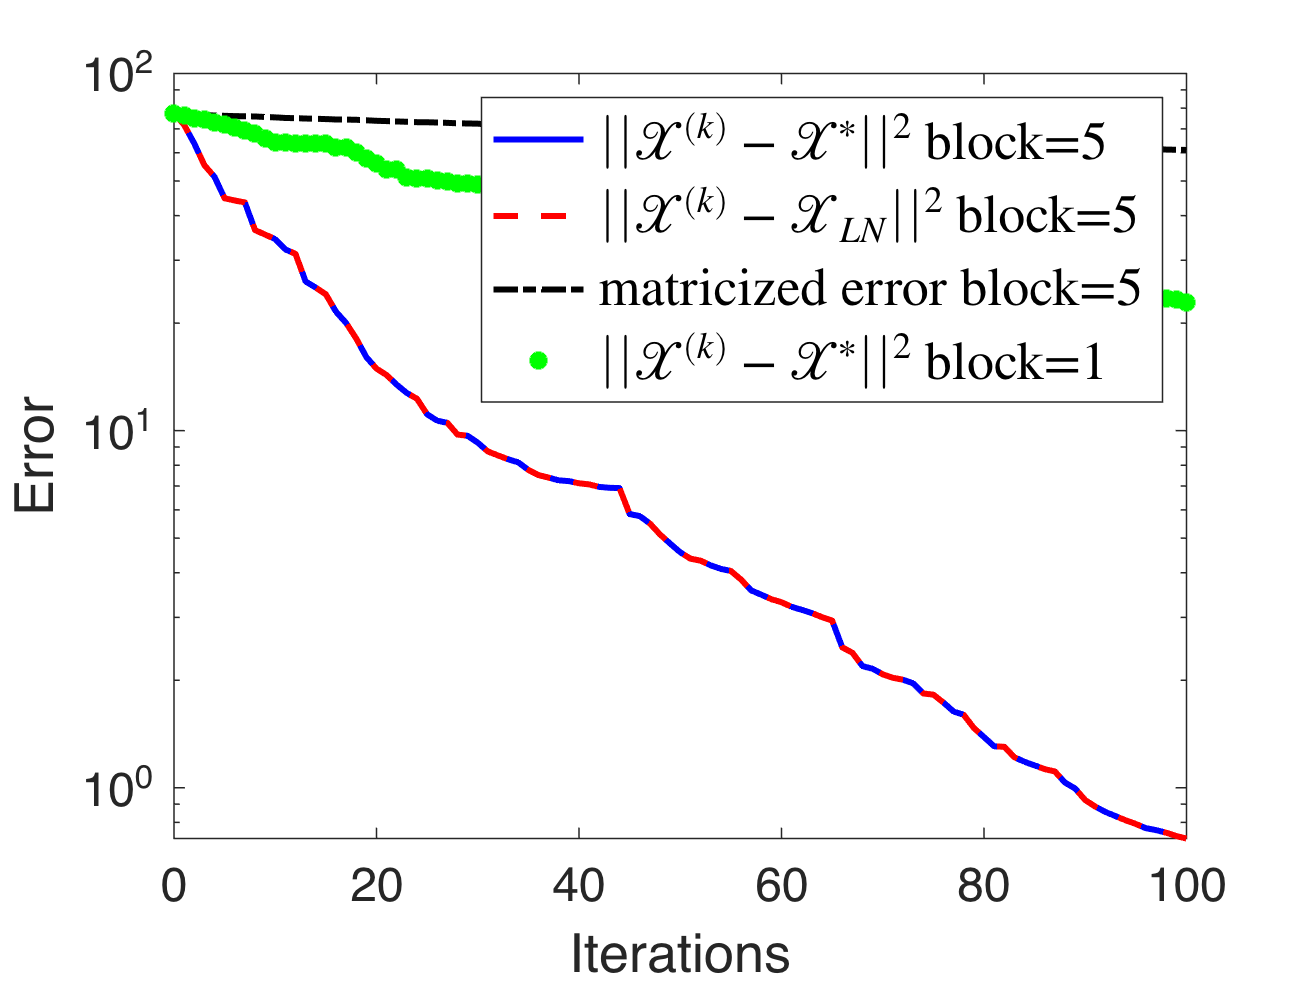

%plot errors vs iterations
figure(1);
semilogy(0:num_its,errs5,'b-',0:num_its,ln_errs5,'r--',0:num_its,mat_errs5,'k-.',0:num_its,errs1,'g*','LineWidth',2)
hold on
set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$ block=5', '$||\mathcal{X}^{(k)} - \mathcal{X}_{LN}||^2$ block=5','matricized error block=5','$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$ block=1','Interpreter','latex','FontSize',18)
hold off